## **Image super resolution simulation using SRCNN**

**Yujin CHO**

*Reference paper : C. Dong, C. C. Loy, K. He, and X. Tang, “Learning a deep convolutional network for image super-resolution,” in Proceedings of the European Conference on Computer Vision, 2014.*

This simulation is implementation of using convolutional neural network for image super resolution(SRCNN). SRCNN is introduced in 2014 and it is first deep learning application on this Super Resolution(SR) field. The Goal is to prove that we can reconstruct better quality of HR(high resolution) image from LR(Low resolution) image using single image compared to traditinal interpolation method(bicubic interpolation).

### **1.Pre-processing**

training = 0    %set to '1' to train a model

training = 0


testing = 1     %set to '1' to test the model

testing = 1



%%%%%%%%%% PRE PROCESSING %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Consider a single low-resolution image, we first upscale it to the desired size using bicubic interpolation, which is the only pre-processing we perform. Let us denote the interpolated image as Y. Our goal is to recover from Y an image F(Y) that is as similar as possible to the ground truth high-resolution image X. For the ease of presentation, we still call Y a “low-resolution” image, although it has the same size as X. We wish to learn a mapping F, which conceptually consists of three operations:

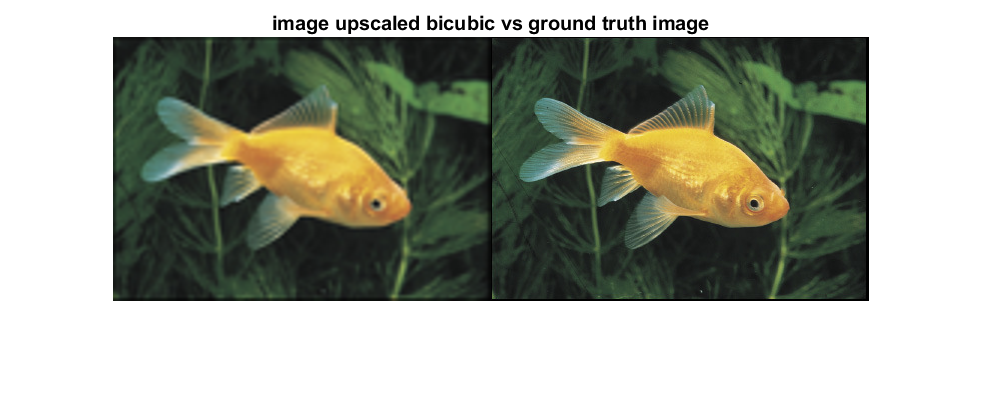

im  = imread('test\n01443537_goldfish.jpeg'); % this is our ground truth image for SR problem (called X)
im_size = size(im);

scaleFactors = 3; % this coeff represent the downgrade applied to the image

im_croped = imresize(im,1/scaleFactors); 
im_bicubic= imresize(im_croped,scaleFactors,'bicubic'); % We reconstruct our image to SR resoltution wanted (called Y)

f1 = figure;
figure(f1);
imshowpair(im_bicubic,im,'montage')
title('image upscaled bicubic vs ground truth image')
axis off

### 2.Model definition

#### [SRCNN architecture]

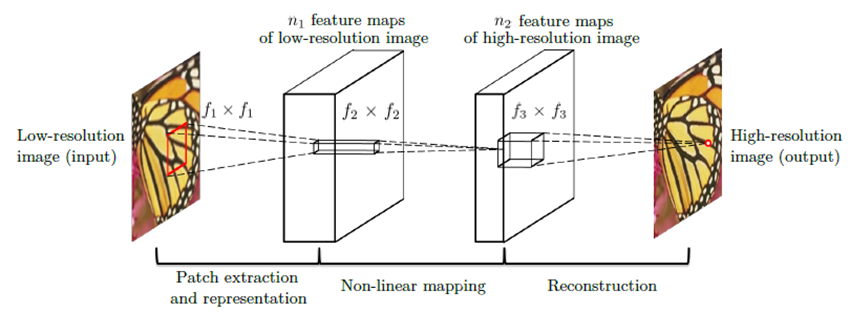

% Goal is to learn the function that can answer F(Y) = X

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% MODEL DEFINITION %%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% model used is 9-1-5 for kernel size and 64-32 for channels
%for simplicity we will work in grayscale with illuminance

inputSize = [32 32 1]; %


layersNetwork = [
    imageInputLayer(inputSize,'Normalization','none','Name','in')

**1) Patch extraction and representation:** this operation extracts (overlapping) patches from the lowresolution image Y and represents each patch as a high-dimensional vector. These vectors comprise a set of feature maps, of which the number equals to the dimensionality of the vectors.

Rectified Linear Unit (ReLU) which makes convergence much faster while still presents good quality

To avoid border effects during training, all the convolutional layers have no padding,


$$F_1 \left(Y\right)=\max \left(0,W_1 *Y+B_1 \right)$$


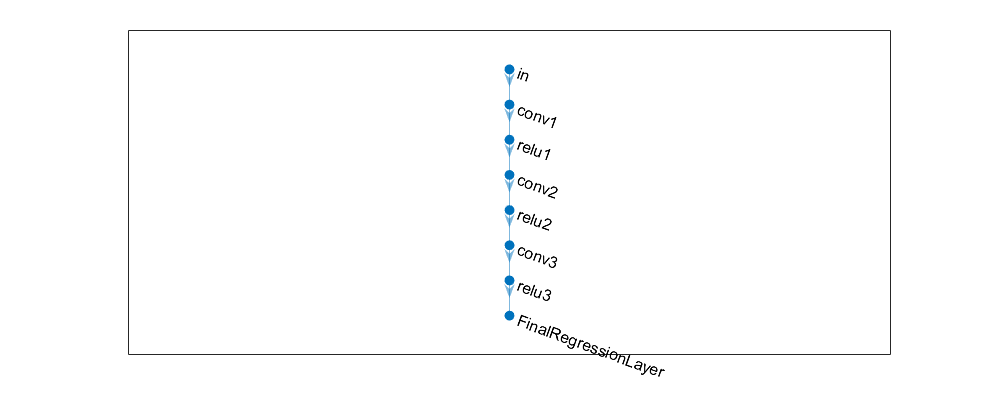

% First layer - Patch extraction and representation
% Kernel size = 9
% Channels = 64

    convolution2dLayer(9,64,'Stride',1,'Padding','same','Name','conv1','WeightsInitializer', 'narrow-normal','BiasInitializer','zeros')   
    reluLayer('Name','relu1')

**2) Non-linear mapping:** this operation nonlinearly maps each high-dimensional vector onto another high-dimensional vector. Each mapped vector is conceptually the representation of a high-resolution patch. These vectors comprise another set of feature maps.


$$F_2 \left(Y\right)=\max \left(0,W_2 *F_1 \left(Y\right)+B_2 \right)$$


% Second layer - Non-linear mapping
% Kernel size = 1
% Channels = 32

    convolution2dLayer(1,32,'Stride',1,'Padding','same','Name','conv2','WeightsInitializer', 'narrow-normal','BiasInitializer','zeros')
    reluLayer('Name','relu2')

**3) Reconstruction:** this operation aggregates the above high-resolution patch-wise representations to generate the final high-resolution image. This image is expected to be similar to the ground truth X.


$$F_3 \left(Y\right)=\max \left(0,W_3 *F_2 \left(Y\right)+B_3 \right)$$


% Third layer - Reconstruction
% Kernel size = 5
% Channels = 3
% WeightsInitializer = 'narrow-normal' – Initialize the weights by independently sampling from a normal distribution with zero mean and standard deviation 0.01
%BiasInitializer = zeros
% WeightLearnRateFactor = 0.0001 * 0.1 = 10^-5

    convolution2dLayer(5,1,'Stride',1,'Padding','same','Name','conv3','WeightsInitializer', 'narrow-normal','BiasInitializer','zeros','WeightLearnRateFactor',0.1)
    reluLayer('Name','relu3')
    regressionLayer('Name','FinalRegressionLayer')];

lNetwork=layerGraph(layersNetwork);
plot(lNetwork)


%disp(SRCNN.Layers)

### 3.Training dataset preparation

PSNR for Bicubic Interpolation: 33.288887 dB


SSIM for Bicubic Interpolation: 0.911811


----------------------------------------

PSNR for SRCNN Reconstruction: 33.351465 dB


SSIM for SRCNN Reconstruction: 0.914257


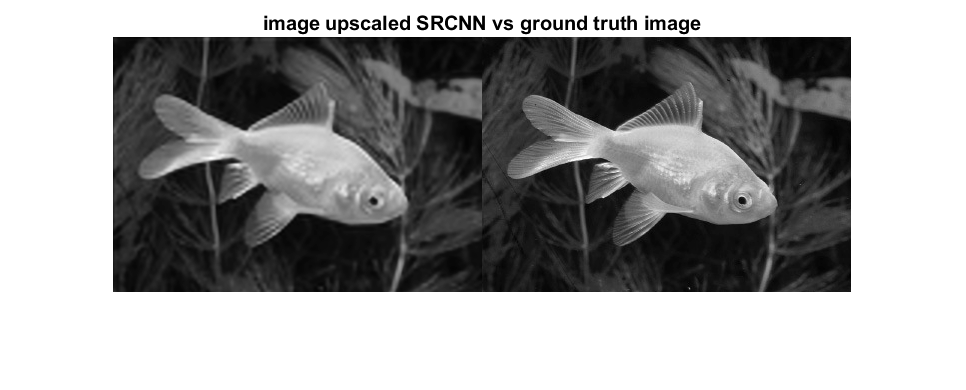

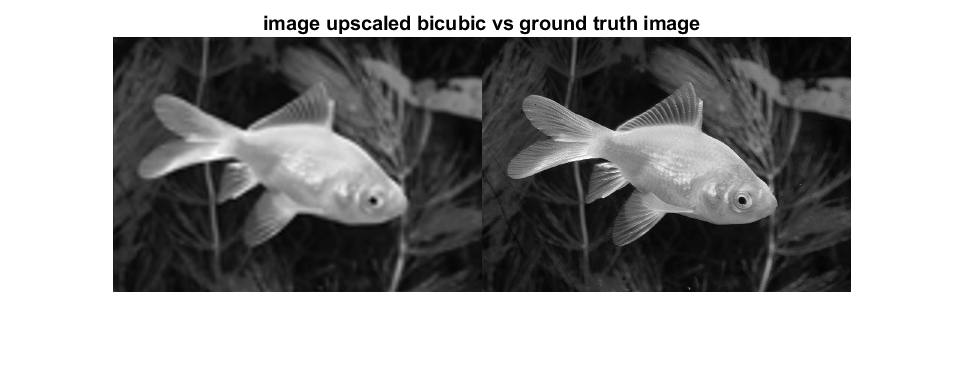

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%% TRAINING DATASET %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

The training dataset used was a sample of the Imagenet dataset `(~1000 files)`

In the training phase, the ground truth images $\left\lbrace X_i \right\rbrace$ are prepared as $f_{\textrm{sub}} \times f_{\textrm{sub}} \times c$ pixel sub-images from the training images.

if(training)

    training_imagepath = ['D:\School_projects\SRCNN\Imagenet_samples'];
    training_imds = imageDatastore(training_imagepath);
    
    GT_DirName = [training_imagepath filesep 'GT'];
    Bicubic_up_DirName = [training_imagepath filesep 'Bicubic_up'];
    
    % The createTrainingSet function is to create transform our images ( working on Illuminance only) and create 2 Dataset : 
    % - Training dataset (Bicubic images)
    % - Expected result dataset ( Ground truth images)
    %/!\ it request many computation to manage many files
    %scaleFactors = 3;
    
    %createTrainingSet(training_imds,scaleFactors,Bicubic_up_DirName,GT_DirName);
    
    
    GroundTruth = imageDatastore(GT_DirName,'FileExtensions','.mat','ReadFcn',@matRead);
    BicUpsampled = imageDatastore(Bicubic_up_DirName,'FileExtensions','.mat','ReadFcn',@matRead);
    
    %Allow us to take 40 random crop from each images of paired dataset, 
    % we increase the number of training elements
    %total images available for dataset = number of image in dataset * patchesPerImage
    
    patchSize = [32 32];
    patchesPerImage = 40;
    dsTrain = randomPatchExtractionDatastore(BicUpsampled,GroundTruth,patchSize, ...
        "PatchesPerImage",patchesPerImage);
    
    % Display some informations about the dataset
    disp(dsTrain.NumObservations) 
    inputBatch = preview(dsTrain);
    disp(inputBatch)

### 4. Hyper parameters setting  and Training

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%% HYPER PARAMETERS %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Learning the end-to-end mapping function $F$ requires the estimation of network parameters $\Theta =\left\lbrace W_1 ,W_2 ,W_3 ,B_1 ,B_2 ,B_3 \right\rbrace$. This is achieved through minimizing the loss between the reconstructed images $F\left(Y;\Theta \right)$  and the corresponding ground truth highresolution images $X$. Given a set of high-resolution images $\left\lbrace X_i \right\rbrace$ and their corresponding low-resolution images $\left\lbrace Y_i \right\rbrace$

- We use Mean Squared Error (MSE) as the loss function: $L\left(\Theta \right)=\frac{1}{n}\;\sum_{i=1}^n {\left\|F\left(Y_i ;\Theta \right)-X_i \right\|}^2$  where n is the number of training samples.

- The loss is minimized using stochastic gradient descent with the standard backpropagation

- The filter weights of each layer are initialized by drawing randomly from a Gaussian distribution with zero mean and standard deviation 0.001 (and 0 for biases).

- The learning rate is $10^{-4}$ for the first two layers, and $10^{-5}$ for the last layer

maxEpochs = 75;
epochIntervals = 1;
initLearningRate = 0.0001;
l2reg = 0.0001;
miniBatchSize = 64;
options = trainingOptions('adam', ...
    'InitialLearnRate',initLearningRate, ...
    'L2Regularization',l2reg, ...
    'shuffle','every-epoch',...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment',"auto",...
    'Verbose',false);

% these parameters are used for learning rate decay
% learningRateFactor = 0.1;
%%%% to include in trainingOptions %%%%%
%     'LearnRateSchedule','piecewise', ...
%     'LearnRateDropPeriod',10, ...
%     'LearnRateDropFactor',learningRateFactor, ...
    
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%% TRAINING FUNCTION %%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This launches the  training of the model
% /!\ it requests many computation /!\



    net = trainNetwork(dsTrain,lNetwork,options);
    modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));
    save(strcat("trainedSRCNN-",modelDateTime,"-Epoch-",num2str(maxEpochs),"-ScaleFactors-4.mat"),'net');
end

### **Detail  training information**

Training is excuted nearly 13hours (total 125epochs) to achieve the result. 

**1)At first training**, 50 epochs of training is done with learning late decay(initial learning rate 0.1, and decay 1/10 times every 10 epochs.)

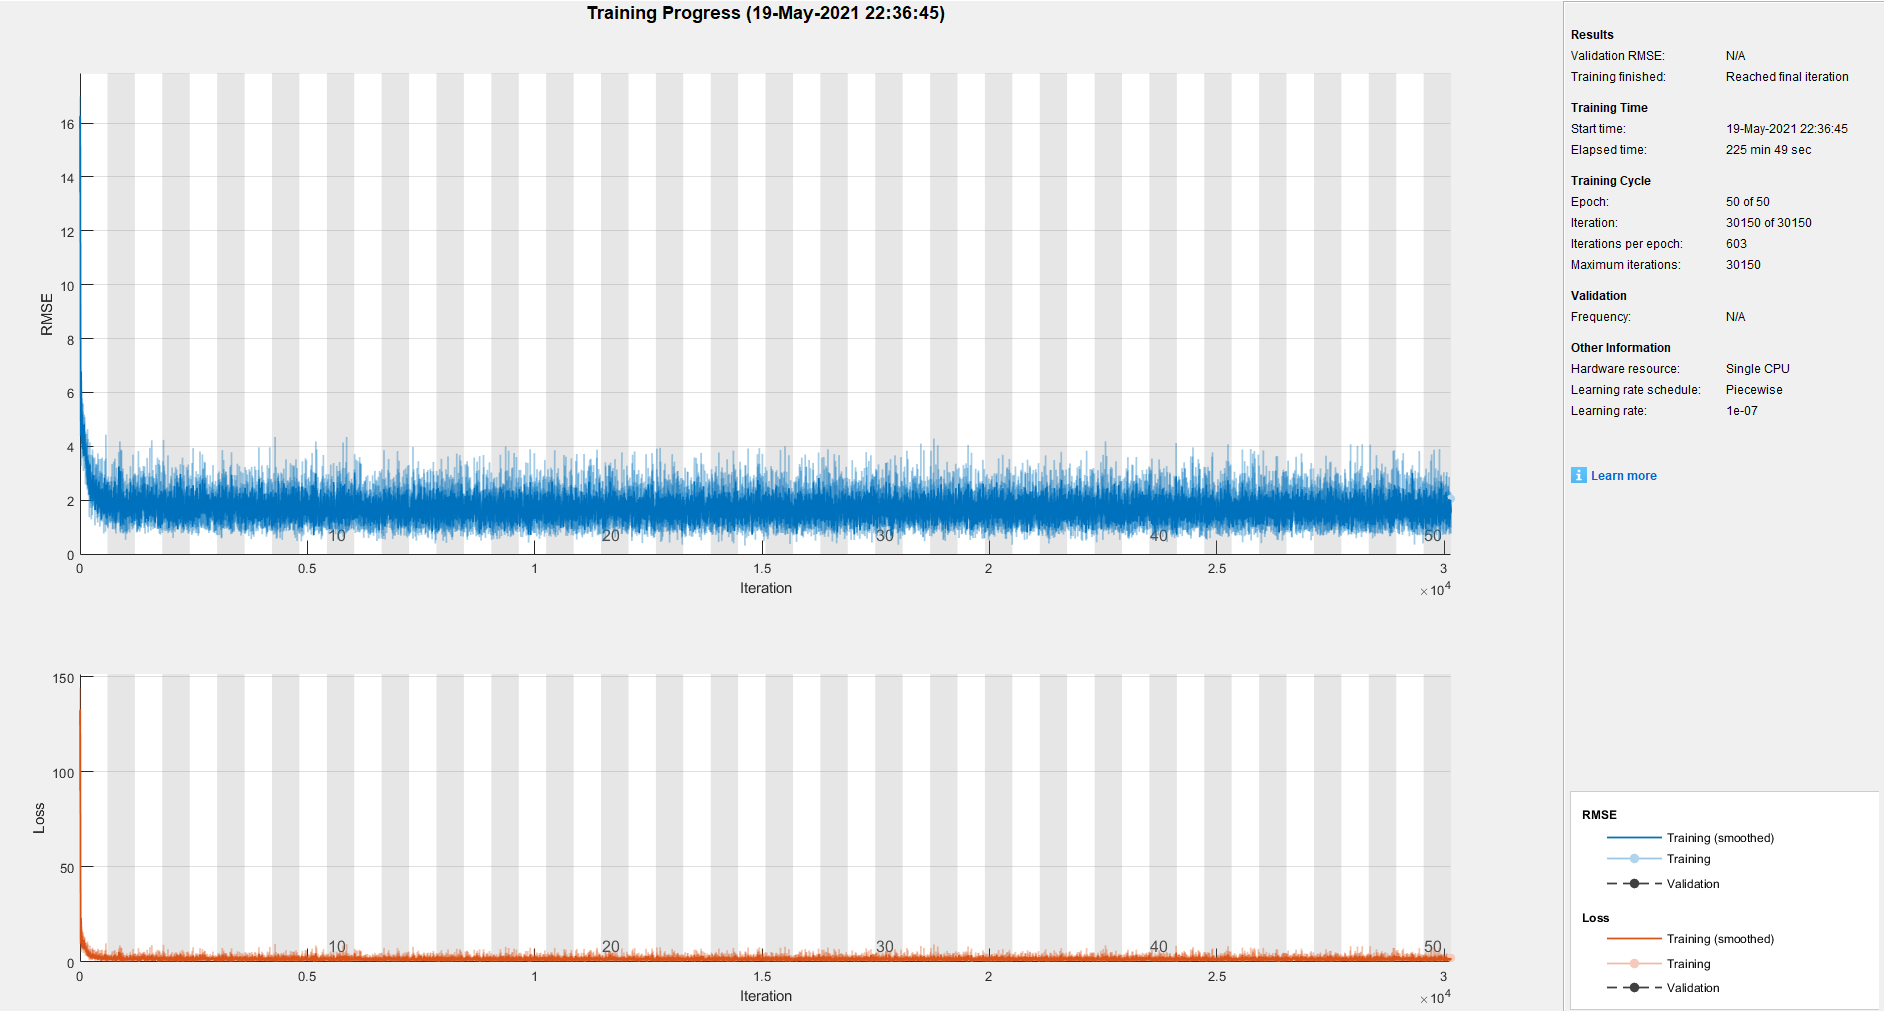

**2)Second training** was done by loading previous training result, 75 epochs were continued with learning late 0.0001.

In this time, we keep same learning rate respecting to original paper.  

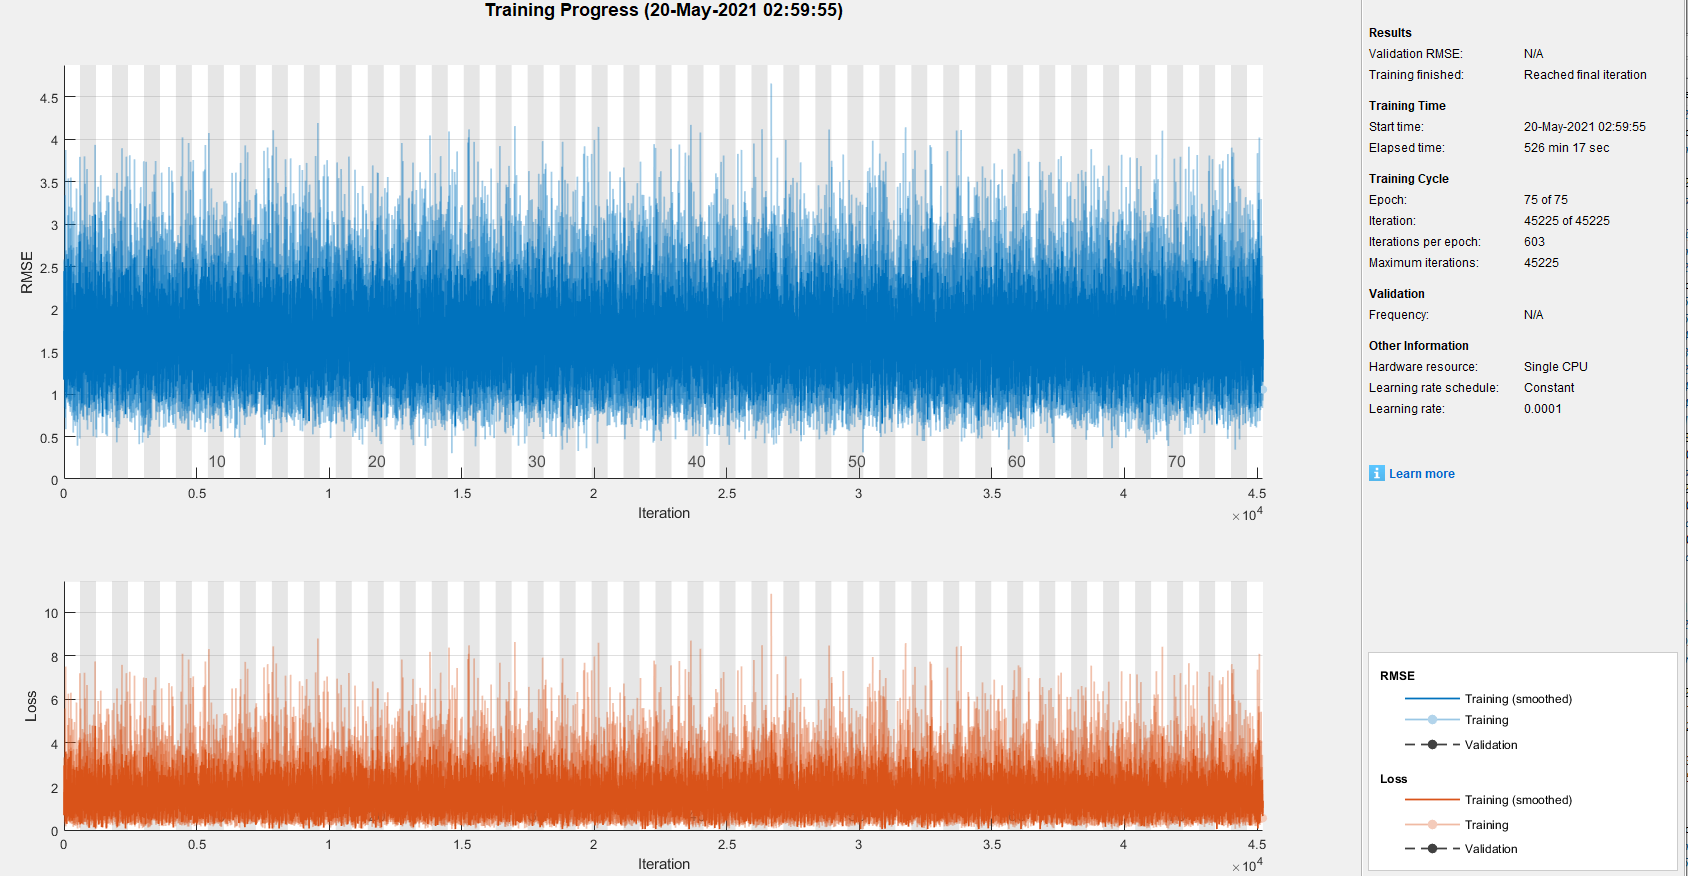

**Improvement :**

As learning rate is small, this CNN requires** many **training, improvement that can be made on this project could be to increase the size of dataset + train more the model.

### 5. Evaluate /Test model

To evaluate model, we compute PSNR and SSIM and compare (for bicubic interpolation and SRCNN reconstruction).

**PSNR** : Signal to noise ratio. The bigger, usually better quality of image 

**SSIM** : It ranges between -1 and 1, If two images are equal the value is 1. The near value 1, it means it is similar with ground truth.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%% TEST MODEL %%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
if(testing)
    %up_scale = 3;
    scaleFactors = 3;
    
    %file used to test
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%%%%You can test each test image to compare PSNR and SSIM value %%%%%
    %We can see PSNR and SSIM is higher in SRCNN, when we compare image by
    %eyes, bicubic image is more blurred than SRCNN reconstructed.
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    im  = imread('test\n01443537_goldfish.jpeg');
    %im  = imread('test\n01685808_whiptail.jpeg');
    %im  = imread('test\n01664065_loggerhead.jpeg');
    %im  = imread('test\n01641577_bullfrog.jpeg');
    %im  = imread('test\n01631663_eft.jpeg');
    %im  = imread('test\n01616318_vulture.jpeg');
    %im  = imread('test\n01669191_box_turtle.jpeg');
    %%%%%%%%%%% Pre processing %%%%%%%%%%%
    
    if size(im,3)>1
        im = rgb2ycbcr(im);
        im = im(:, :, 1); %% work on illuminance only
    end
    im_gnd = modcrop(im, scaleFactors);
    im_gnd = single(im_gnd)/255;
    
    im_l = imresize(im_gnd, 1/scaleFactors);
    im_b = imresize(im_l, scaleFactors, 'bicubic');%% bicubic interpolation for input image
    
    %%%%%%%% End of Pre processing %%%%%%%%%
    
    %We give our Bicubic upsampled image to this SRCNN function
    % As SRCNN was trained with patches of [32 32], this function will divide
    % our images into sub images of [32 32] and reconstruct it completely in
    % order to have the best result
    
    im_h = SRCNN_reconstruct('trainedSRCNN-2021-05-20-11-46-13-Epoch-75-ScaleFactors-3',im_b);
    
    % setting back to grayscale and remove border
    im_h = shave(uint8(im_h * 255), [scaleFactors, scaleFactors]);
    im_gnd = shave(uint8(im_gnd * 255), [scaleFactors, scaleFactors]);
    im_b = shave(uint8(im_b * 255), [scaleFactors, scaleFactors]);
    
    % compute PSNR
    % Peak signal-to-noise ratio (PSNR) is an engineering term for the ratio between the maximum
    % possible power of a signal and the power of corrupting noise that affects the fidelity of its representation.
    
    psnr_bic = compute_psnr(im_gnd,im_b);
    psnr_srcnn = compute_psnr(im_gnd,im_h);
    
    %compute SSIM
    %The structural similarity index measure (SSIM) is a method for predicting the perceived quality 
    % of digital television and cinematic pictures, as well as other kinds of digital images and videos. 
    % SSIM is used for measuring the similarity between two images.
    
    ssim_bic = ssim(im_b,im_gnd);
    ssim_srcnn = ssim(im_h,im_gnd);
    
    % show results
    fprintf('PSNR for Bicubic Interpolation: %f dB\n', psnr_bic);
    fprintf('SSIM for Bicubic Interpolation: %f\n', ssim_bic);
    fprintf('----------------------------------------');
    fprintf('PSNR for SRCNN Reconstruction: %f dB\n', psnr_srcnn);
    fprintf('SSIM for SRCNN Reconstruction: %f\n', ssim_srcnn);
    
%     figure, imshow(im_gnd); title('Original image');
%     figure, imshow(im_b); title('Bicubic Interpolation');
%     figure, imshow(im_h); title('SRCNN Reconstruction');
    
    figure();
    imshowpair(im_h,im_gnd,'montage')
    title('image upscaled SRCNN vs ground truth image')
    axis off
    figure();
    imshowpair(im_b,im_gnd,'montage')
    title('image upscaled bicubic vs ground truth image')
    axis off
end

#### Results :

We can see here result for a test image, we can see that the 2 metrics (PSNR and SSIM) express an improvements in the reconstitution. Visually we can clearly see that the reconstructed image has a 'better' quality than the bicubic image. Of course the result is better but still we couldn't achieve to reach the quality of the ground truth image.

If we watch for PSNR metric, it can happen that the PSNR of reconstructed image will not always higher than Bicubic. When we perform optimization, we minimize mean squre error(MSE) between ground trouth and recovered HR image. It is convinient as minimizing MSE also maximizes the peak signal to noise ratio(PSNR). However, the ability of MSE and PSNR to capture perceptually relevant differences such as high texture detail is very limited as they are deifined on pixel wise image differences. Therefore the highest PSNR doesn't necesarrily means it is perceptually better for SR Result. 

 That's why we are also using SSIM which is measurement based on three factors (luminance, constrast, and structure) to better suit for the human visual systems. We can see that PSNR and SSIM results are slightly higher for SRCNN reconstructed case than bicubic interpolation.(below Figure). There was some cases PSNR was little bit lower but SSIM was higher, however when we see image by eyes qualtiy was better for SRCNN reconstructed. 

To improve our model result, we can increase the number of samples in dataset and train more epochs. (Training with single CPU was constrained in my case, 12h training took).

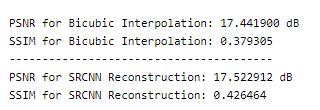

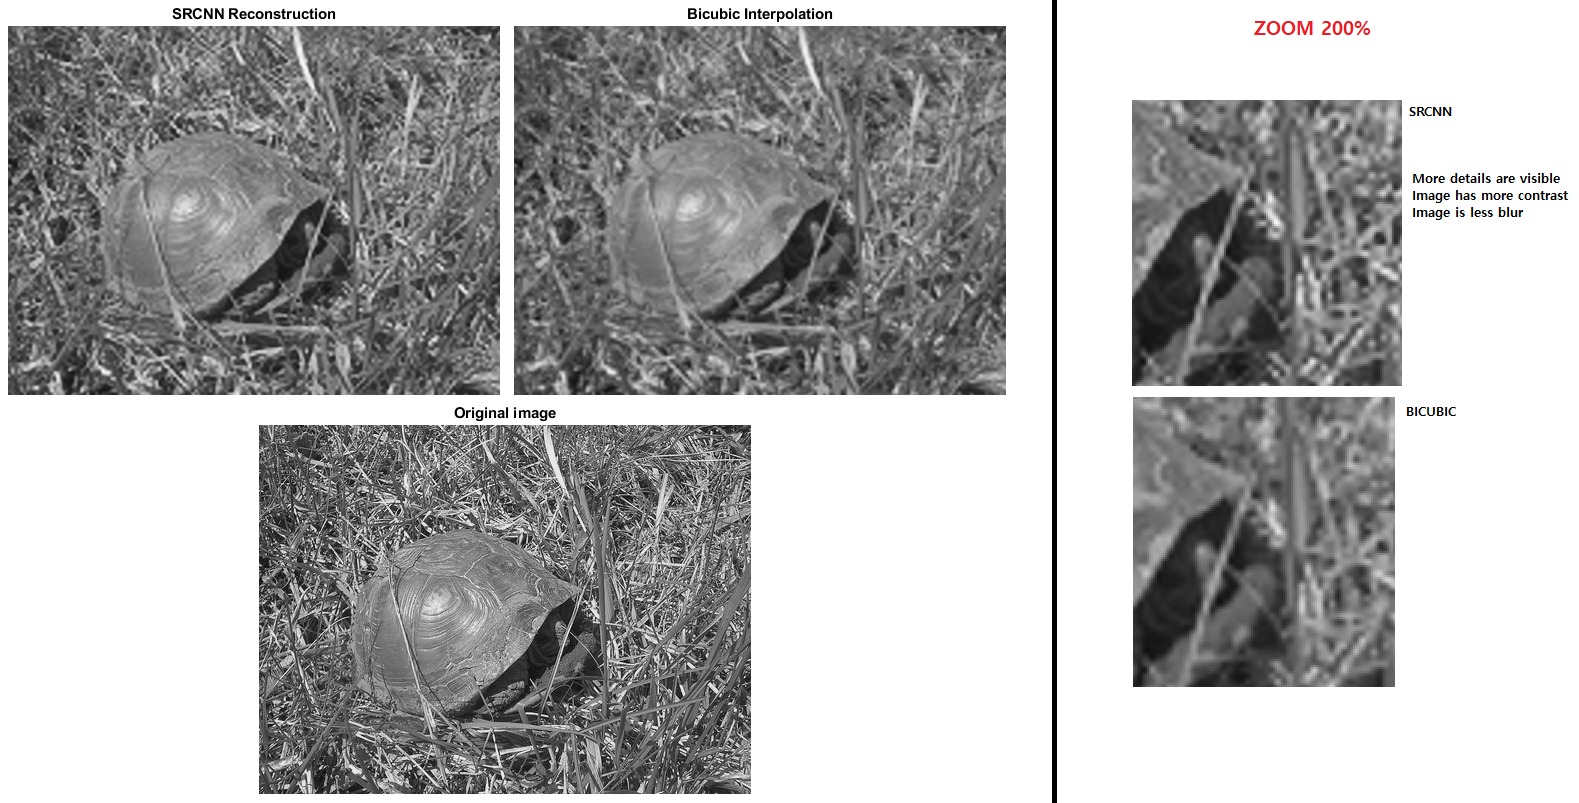

### **Function define **

create training set , reconstruct with trained mat file

function createTrainingSet(imds,scaleFactors,BICupsampledDirName,GTDirName)
%This function allow us to create specific dataset to train srcnn
% - Training dataset (Bicubic images)
% - Expected result dataset ( Ground truth images)

if ~isfolder(GTDirName) %We create directories if they are not available yet
    mkdir(GTDirName);
end
    
if ~isfolder(BICupsampledDirName)
    mkdir(BICupsampledDirName);
end

    
    while hasdata(imds)
        % Use only the luminance component for training
        [I,info] = read(imds);
        [~,fileName,~] = fileparts(info.Filename);

        I = rgb2ycbcr(I);
        Y = I(:,:,1); % We recover the illuminance of all the images
        
        GroundTruth = im2double(Y); % We save the ground truth image
        
        %We compute the bicubic by downgrading the ground truth image the
        %upscaling zith bicubic function
        
        im_croped = imresize(GroundTruth,1/scaleFactors);
        BICupsampledImage= imresize(im_croped,[size(I,1) size(I,2)],'bicubic'); 
        
        save([GTDirName filesep fileName '.mat'],'GroundTruth'); %We save to mat files both GT and Upsampled bicubic image
        save([BICupsampledDirName filesep fileName '.mat'],'BICupsampledImage');

    end

end

function data = matRead(filename)
%This function allow us to read a mat file

inp = load(filename);
f = fields(inp);
data = inp.(f{1});

end

function imgs = modcrop(imgs, modulo)
    if size(imgs,3)==1
        sz = size(imgs);
        sz = sz - mod(sz, modulo);
        imgs = imgs(1:sz(1), 1:sz(2));
    else
        tmpsz = size(imgs);
        sz = tmpsz(1:2);
        sz = sz - mod(sz, modulo);
        imgs = imgs(1:sz(1), 1:sz(2),:);
    end
end

function I=shave(I,border)
I=I(1+border(1):end-border(1),1+border(2):end-border(2),:,:);
end

function im_h = SRCNN_reconstruct(net,im_b)
    %We load our net DAGNetwork
    load(net);
    
    %We recover all weights of the Network and reshape for reconstruction needs
    biases_conv1_t = net.Layers(2, 1).Bias;
    for i =1:64
        biases_conv1(i) = biases_conv1_t(1,1,i);
        biases_conv1 = biases_conv1';
    end
    biases_conv2_t = net.Layers(4, 1).Bias;
    for i =1:32
        biases_conv2(i) = biases_conv2_t(1,1,i);
        biases_conv2 = biases_conv2';
    end
    
    biases_conv3 = net.Layers(6, 1).Bias;
    
    weights_conv1_t = double(net.Layers(2, 1).Weights);
    for i =1:64
        weights_conv1(:,i)= reshape(weights_conv1_t(:,:,i),[81 1]);
    end
    
    weights_conv2_t = double(net.Layers(4, 1).Weights);
    for j =1:32
          weights_conv2(:,1,j)= reshape(weights_conv2_t(:,:,:,j),[64 1]);
    end
  
    weights_conv3_t = double(net.Layers(6, 1).Weights);
    for i =1:32
        weights_conv3(:,i)= reshape(weights_conv3_t(:,:,i),[25 1]);
    end
    
    %%SRCNN reconstruction
    [conv1_patchsize2,conv1_filters] = size(weights_conv1);
    conv1_patchsize = sqrt(conv1_patchsize2);
    [conv2_channels,conv2_patchsize2,conv2_filters] = size(weights_conv2);
    conv2_patchsize = sqrt(conv2_patchsize2);
    [conv3_patchsize2,conv3_channels] = size(weights_conv3);
    conv3_patchsize = sqrt(conv3_patchsize2);
    [hei, wid] = size(im_b);
    % 
    %% conv1
    weights_conv1 = double(reshape(weights_conv1, conv1_patchsize, conv1_patchsize, conv1_filters));
    conv1_data = zeros(hei, wid, conv1_filters);
    for i = 1 : conv1_filters
        conv1_data(:,:,i) = imfilter(im_b, weights_conv1(:,:,i), 'same', 'replicate');
        conv1_data(:,:,i) = max(conv1_data(:,:,i) + biases_conv1(i), 0);
    end
    %% conv2
    conv2_data = zeros(hei, wid, conv2_filters);
    for i = 1 : conv2_filters
        for j = 1 : conv2_channels
            conv2_subfilter = reshape(weights_conv2(j,:,i), conv2_patchsize, conv2_patchsize);
            conv2_data(:,:,i) = conv2_data(:,:,i) + imfilter(conv1_data(:,:,j), conv2_subfilter, 'same', 'replicate');
        end
        conv2_data(:,:,i) = max(conv2_data(:,:,i) + biases_conv2(i), 0);
    end
    
    %% conv3
    conv3_data = zeros(hei, wid);
    for i = 1 : conv3_channels
        conv3_subfilter = double(reshape(weights_conv3(:,i), conv3_patchsize, conv3_patchsize));
        conv3_data(:,:) = conv3_data(:,:) + imfilter(conv2_data(:,:,i), conv3_subfilter, 'same', 'replicate');
    end
    
    %% SRCNN reconstruction
    im_h = conv3_data(:,:) + biases_conv3;

end

function psnr=compute_psnr(im1,im2)

    imdff = double(im1) - double(im2);
    imdff = imdff(:);
    
    rmse = sqrt(mean(imdff.^2));
    psnr = 20*log10(255/rmse);

end